# **Лабораторная работа №2**

## **Планирование траектории многозвенного манипулятора**

**Студент: Топольницкий А.**

**Группа: R4134c**

**Поток: МИУР 1.1**

**Вариант: 2 **

**Робот: ABB IRB140**

***Задание:***

- *Задать начальное положение звеньев манипулятора и решить прямую задачу кинематики для определения начального положения схвата в операционном пространстве*

- *Построить рабочую зону манипулятора*

- *Выбрать конечное положение схвата манипулятора из допустимых значений*

- *Спланировать траекторию между начальным и конечным положением схвата манипулятора с использованием нескольких способов интерполяции*

- *Вывести изменение компонент уравнения динамики при движении вдоль выбранной траектории*

- *Создать генератор траектории и спланировать движение манипулятора, исходя из ранее проделанных шагов, в Simulink*

#### ***Ход работы***

close all
clear all
clc
mdl_irb140

Пункт 1. Задать начальное положение звеньев манипулятора и решить прямую задачу кинематики

qst = [pi/4 pi/4 pi/10 pi/10 pi/15 pi/5]; % задание начального положения звеньев
Kin = irb140.fkine(qst); % решение прямой задачи кинематики

Пункт 2. Построение рабочей зоны манипулятора

Для начала необходимо задать ограничения для звеньев манипулятора. Возьмём из официальной документации, переведём в радианы.

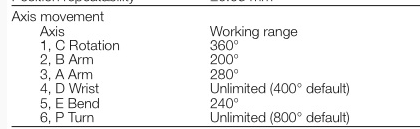

lims = deg2rad([-180 180 ; -100 100; -140 140; -200 200; -120 120; -400 400]);  % переводим градусы в радианы для каждого звена
% задаём ограничения для каждого из звеньев
for i = 1:6
    irb140.qlim(i,1) = lims(i,1);
    irb140.qlim(i,2) = lims(i,2);
end

Теперь рассчитаем рабочую зону манипулятора. Поскольку у робота 3 последних звена представляют собой сферическое звено, то на рабочу зону влияют первые три обобщённые координаты

i = 1; % задаём счётчик
n = 30; % количество точек расчёта по каждой координате
pose = zeros(3, n^3);
lim = irb140.qlim;
for q1 = linspace(lim(1,1), lim(1,2), n) % перебираем по всем трём координатам
    for q2 = linspace(lim(2,1), lim(2,2), n)
        for q3 = linspace(lim(3,1), lim(3,2), n)
            q = [q1 q2 q3 0 0 0];
            pose0 = irb140.fkine(q);  % для каждой точки решаем ПЗК
            pose0 = pose0.t; % получить столбец с коориднатами
        end
        pose(:,i) = pose0;
        i = i + 1;
    end
end

Построим 3D график рабочей области

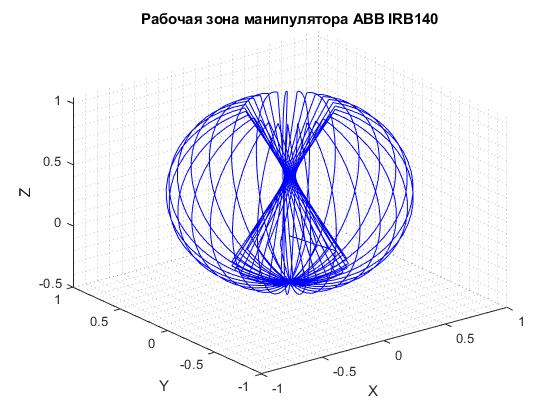

X = pose(1,:);
Y = pose(2,:);
Z = pose(3,:);
plot3(X,Y,Z, 'Color','b')
xlabel('X')
ylabel('Y')
zlabel('Z')
grid minor
title('Рабочая зона манипулятора ABB IRB140')

Пункт 3. Выбрать конечное положение схвата исходя из допустимых значений

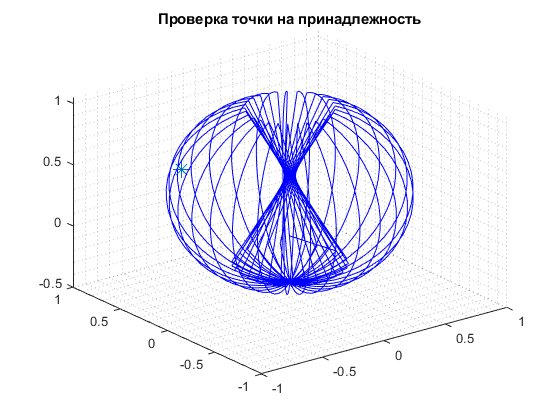

clf
%dot = [-0.6 0.1 0.7];
%dot = [0.4 0.2 0.6];
dot = [-0.5 0.5 0.5];
plot3(dot(1),dot(2),dot(3), "Marker","*","MarkerSize",12)
hold on
grid minor
plot3(X,Y,Z, 'Color','b') % отобразим для проверки
title ('Проверка точки на принадлежность')

Пункт 4. Спланировать траекторию между начальным и конечным положением схвата манипулятора с использованием нескольких способов интерполяции.

Найти конечную конфигурацию робота можно, знаю точку, с помощью функции ikine6s для робота со сферическим звеном. 

t = [0:0.01:2]'; % задаём время пути
qend=irb140.ikine6s(transl(dot) * trotx(pi/2) * troty(pi/3) * trotz(pi/4)); % transl - линейная составляющаяя однородной матрицы, trotx - вращательная
% составляющая вокруг оси х, y, z

1 способ - использование функции jtraj

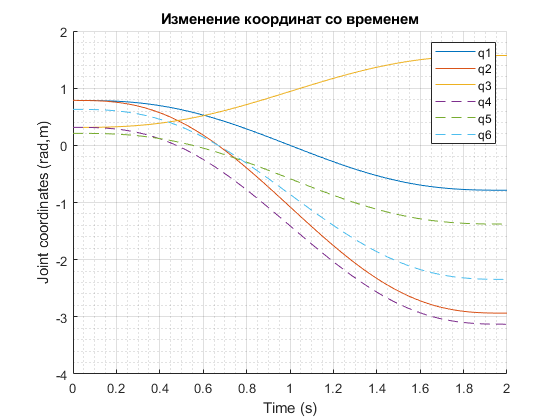

[q, q_d, q_dd] = jtraj(qst,qend,t);
q = jtraj(qst,qend,t);
figure
qplot(t, q);
title ('Изменение координат со временем')
grid minor

2 способ - использование функции mtraj  и lspb

lspb - на траектории есть участок с постоянной скоростью и 2 участка (ускорение и торможение) с полиномиальной зависимостью

mtraj - позволяет использовать lspb для многомерного случая

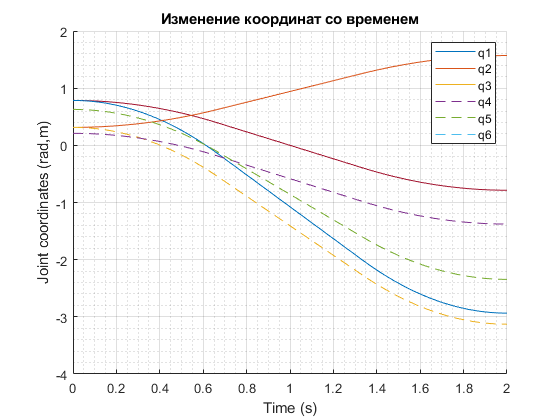

[q1, q_d, q_dd] = mtraj(@lspb, qst, qend,t);
qq = mtraj(@lspb, qst, qend,t);
figure
qplot(t,qq)
hold on
qplot(t,q1)
title ('Изменение координат со временем')
grid minor

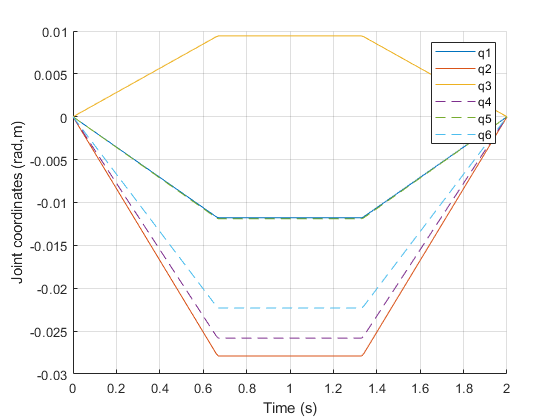


figure
qplot(t,q_d)

Можно для каждого звена по отдельности вывести трапецевидный профиль скорости

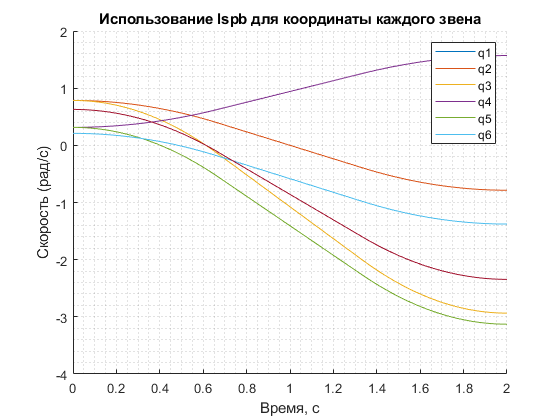

figure
for i = 1:6
    hold on
    [ql, qd, qdd] = lspb(qst(i), qend(i), t);
    plot(t,ql)
    plot(t,q1)
end
title('Использование lspb для координаты каждого звена')
grid minor
ylabel('Скорость (рад/c)')
xlabel('Время, с')
legend('q1','q2','q3','q4','q5','q6')

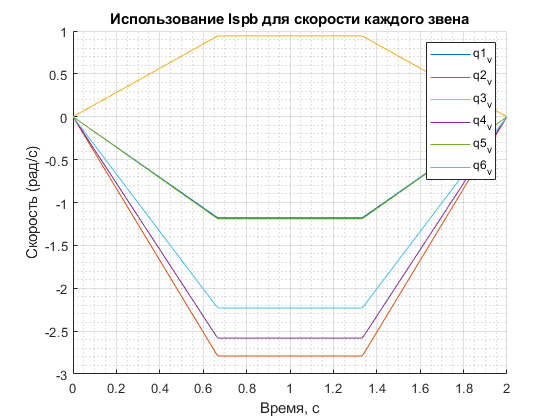


figure
for i = 1:6
    hold on
    [q, qd, qdd] = lspb(qst(i), qend(i), t);
    plot(t,qd)
end
grid on
ylabel('Скорость (рад/c)')
xlabel('Время, с')
title('Использование lspb для скорости каждого звена')
legend('q1_v','q2_v','q3_v','q4_v','q5_v','q6_v')
grid minor

Пункт 5. Вывести изменение компонент уравнения динамики при движении вдоль выбранной траектории

Часть кода возьмём из первой лабораторной работы

m = [10 8 6 4 2 2];

for i = 1:6
    irb140.links(1,i).m = m(i);
end
w = [0.08 0.06 0.06 0.04 0.04 0.02];

for i = 1:6
    irb140.links(1,i).r = [irb140.links(1,i).a/2 0 0];
end
for i=1:6
    irb140.links(1,i).I = zeros(3,3);
end

for i=1:6
    if i == 1
        irb140.links(1,i).I(1,1) = 1/12 * m(i) * (w(i)^2 + irb140.links(1,i).a^2);
        irb140.links(1,i).I(2,2) = 1/12 * m(i) * 2 * w(i)^2;
        irb140.links(1,i).I(3,3) = 1/12 * m(i) * 2 * w(i)^2;
    else
        irb140.links(1,i).I(1,1) = m(i) * (w(i) / 2)^ 2;
        irb140.links(1,i).I(2,2) = 1/12 * m(i) * (3 * (w(i)/2)^2 + irb140.links(1,i).a^2);
        irb140.links(1,i).I(3,3) = 1/12 * m(i) * (3 * (w(i)/2)^2 + irb140.links(1,i).a^2);
    end
end
mdl_puma560
for i = 1:6
    irb140.links(1,i).Jm =p560.links(1,i).Jm;
end

Построим графики для случая, когда траектория рассчитывается через jtraj

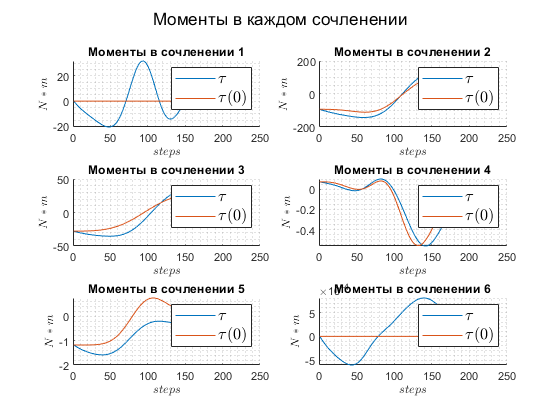

[q, q_d, q_dd] = jtraj(qst,qend,t);
Qp = irb140.rne(q,q_d,q_dd);
Qp0 = irb140.rne(q,zeros(201,6),zeros(201,6)); 
Gp = irb140.gravload(q); % вектор гравитационных сил, совпадает с Qp0
Mp = irb140.inertia(q); % матрица масс
Cp = irb140.coriolis(q, q_d); % вектор кориолисовых и центробежных сил С
figure;
sgtitle('Моменты в каждом сочленении') 
for i = 1:6
    subplot(3,2,i);
    hold on;
    plot(Qp(:,i))
    plot(Qp0(:,i))
    title(['Моменты в сочленении ', num2str(i)])
    ylabel('$N * m$','interpreter','latex');
    xlabel('$steps$','interpreter','latex');
    grid minor;
    legend('$\tau$', '$\tau(0)$', 'fontsize',12,'interpreter','latex');
end

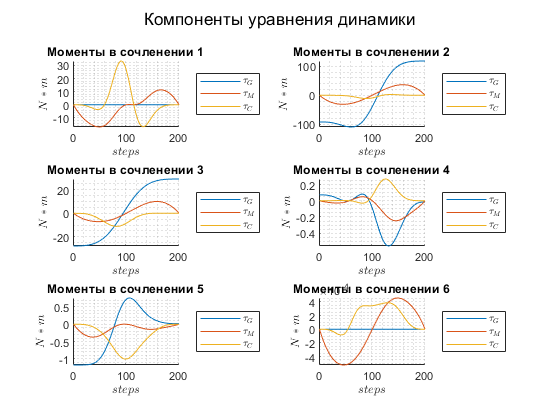

tM = zeros(201, 6);
tc = zeros(201, 6);
for i = 1 : 201
    tM(i,:) = Mp(:,:,i) * q_dd(i,:)'; % берём матрицу инерции 6 х 6 для каждого шага
    % и умножаем её на транспонированное ускорение (6 х 1), получаем момент
    tc(i,:) = Cp(:,:,i) * q_d(i,:)'; % матрицу кор. и центр. сил на трансп. скорость
end
figure
sgtitle('Компоненты уравнения динамики') 
for i=1:6
    subplot(3,2,i)
    hold on
    plot(Gp(:,i))
    plot(tM(:,i))
    plot(tc(:,i))
    title(['Моменты в сочленении ' , num2str(i)])
    ylabel('$N * m$','interpreter','latex');
    xlabel('$steps$','interpreter','latex');
    grid minor;
    legend('$\tau_G$', '$\tau_M$','$\tau_C$','interpreter','latex','location', 'eastoutside'); 
end

Построим пример траектории, лежащей в рабочей зоне робота, с помощью функции mstraj

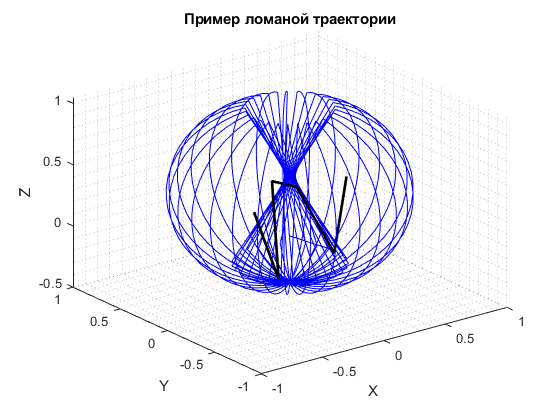

figure
q_path_start = [-0.4 -0.4 -0.4];
path = 0.1 * [-6 -4 5; -4 -4 -1; -3 -2 6; -1 -2 5;
 -1 -6 1; 0 -6 7];
% матрица точек, ограничения по скорости вдоль осей, начальные координаты,
% шаг по времени, максимальное ускорение
plot3(path(:,1), path(:,2), path(:,3), 'color', 'k', 'LineWidth', 2)
p = mstraj(path, [0.1 0.1 0.05], [], q_path_start, 0.01, 0.05);
grid minor
title('Пример ломаной траектории')
xlabel('X')
ylabel('Y')
zlabel('Z')
hold on
plot3(X,Y,Z, 'Color','b')

Tp = transl(0.1 * p);
Tp = homtrans(transl(0.4, 0.2, 0), Tp);
q_path_end = irb140.ikine6s(Tp);
[q, q_d, q_dd] = mtraj(@lspb, [q_path_start pi/4 pi/5 pi/6], q_path_end,t);

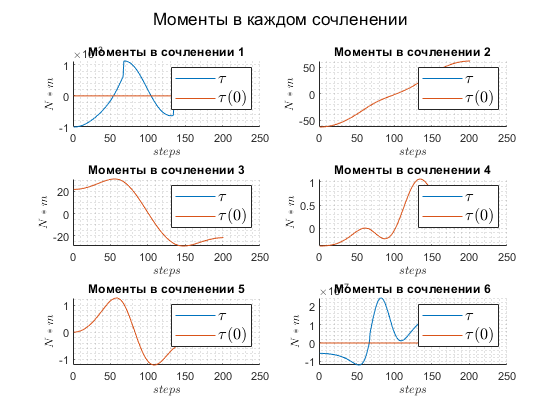

Qp = irb140.rne(q,q_d,q_dd);
Qp0 = irb140.rne(q,zeros(201,6),zeros(201,6)); 
Gp = irb140.gravload(q); % вектор гравитационных сил, совпадает с Qp0
Mp = irb140.inertia(q); % матрица масс
Cp = irb140.coriolis(q, q_d); % вектор кориолисовых и центробежных сил С
figure;
sgtitle('Моменты в каждом сочленении') 
for i = 1:6
    subplot(3,2,i);
    hold on;
    plot(Qp(:,i))
    plot(Qp0(:,i))
    title(['Моменты в сочленении ', num2str(i)])
    ylabel('$N * m$','interpreter','latex');
    xlabel('$steps$','interpreter','latex');
    grid minor;
    legend('$\tau$', '$\tau(0)$', 'fontsize',12,'interpreter','latex');
end

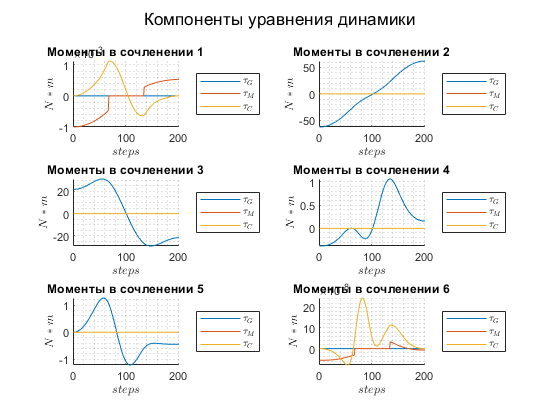

tM = zeros(201, 6);
tc = zeros(201, 6);
for i = 1 : 201
    tM(i,:) = Mp(:,:,i) * q_dd(i,:)'; % берём матрицу инерции 6 х 6 для каждого шага
    % и умножаем её на транспонированное ускорение (6 х 1), получаем момент
    tc(i,:) = Cp(:,:,i) * q_d(i,:)'; % матрицу кор. и центр. сил на трансп. скорость
end
figure
sgtitle('Компоненты уравнения динамики') 
for i=1:6
    subplot(3,2,i)
    hold on
    plot(Gp(:,i))
    plot(tM(:,i))
    plot(tc(:,i))
    title(['Моменты в сочленении ' , num2str(i)])
    ylabel('$N * m$','interpreter','latex');
    xlabel('$steps$','interpreter','latex');
    grid minor;
    legend('$\tau_G$', '$\tau_M$','$\tau_C$','interpreter','latex','location', 'eastoutside'); 
end

Файл в Simulink

Lab2_TopolnitskiiA_R3134c_slx

### **Выводы:**